# Pitch contour. 24.09.2025

associated files:

1) MiniHopperMTB\MLP_Pitch_Contour_6.slx

2) MiniHopperMTB\MLP_Pitch_Contour_7.slx

clc; clear; close all;

Jy = 3e-2;
Jx = 3e-2;
m = 1.68;
Cw = 1e-2;
Cv = 1e-1;
Ts = 0.001;
g = 9.8065;

F = m*g;
Lz = 0.5;
ex = 0.1;
ey = 0.1;

% parameters
param = struct();
param.m = m;
param.Jy = Jy;
param.Cw = Cw;
param.Cv = Cv;
param.Ts = Ts;
param.g = g;
param.Lz = Lz;
param.ex = ex;
param.ey = ey;
params = [m, Jy, Cw, Cv, Ts, g, Lz, ex, Jx, ey];


s = tf('s');

% Plant: M -> w
G_inner   = c2d(1/(Jy*s + Cw), Ts, 'zoh');


% Tunable rate PID
C_rate  = tunablePID('C_rate','PID');
C_rate.Ts  = Ts;
C_rate.Kp.Minimum = 0;
C_rate.Ki.Minimum = 0;
C_rate.Kd.Minimum = 0; 
C_rate.Tf.Minimum = 1 / 1000; 
C_rate.Tf.Maximum = 1 / 10;

% I/O naming
C_rate.InputName  = 'e_w';   C_rate.OutputName  = 'M';
G_inner.InputName = 'M';     G_inner.OutputName = 'w';

% Error summation
Sum_w   = sumblk('e_w = w_ref - w');

% Closed-loop interconnection
CL0 = connect(C_rate, G_inner, Sum_w, ...
              'w_ref', {'w','M'}, ...
              {'e_w'});                 % <-- analysis point here

% Goals
wc_rate  = 2*pi*10;     % ~10 Hz target
wc_angle = 2*pi*5;      % ~3 Hz
wc_vel   = 2*pi*1;      % ~1 Hz
wc_pos   = 2*pi*0.2;    % ~0.2 Hz


tau_w    = 1/wc_rate;
tau_phi = 1 / wc_angle;
tau_v = 1 / wc_vel;
tau_p = 1/ wc_pos;


ReqTrackRate = TuningGoal.Tracking('w_ref','w', tau_w);
ReqMi        = TuningGoal.Margins('e_w', 6, 45);   % robustness on inner loop

GOALS = [ReqTrackRate, ReqMi];

% Tune
[CLwtuned,fSoft] = systune(CL0, GOALS);

Final: Soft = 1.06, Hard = -Inf, Iterations = 41


% Show tuned PID gains
showTunable(CLwtuned)

C_rate =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 3.54, Ki = 1.36, Kd = 1.82e-11, Tf = 0.0185, Ts = 0.001
 
Name: C_rate
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.


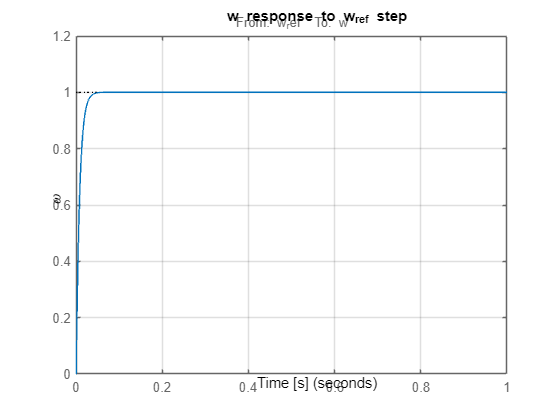

% Transfer function from w_ref to w
T_w = getIOTransfer(CLwtuned,'w_ref','w');

% Plot step response
figure;
step(T_w, 1); grid on;
ylabel('\omega'); xlabel('Time [s]');
title('w response to w_{ref} step');

## Plot

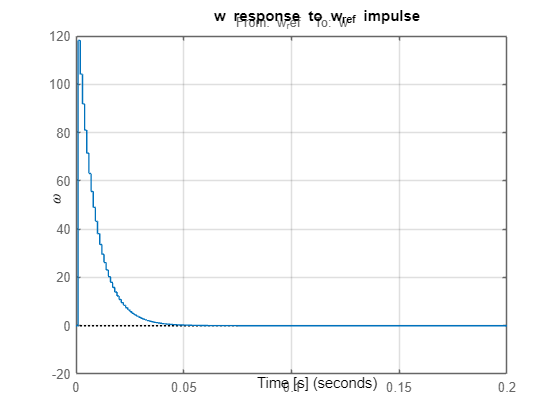

T_w   = getIOTransfer(CLwtuned,'w_ref','w');

figure;
impulse(T_w,  0.2); grid on; 
ylabel('\omega');   
xlabel('Time [s]'); 
title('w response to w_{ref} impulse');

## Look at PID parameters

% Extract tuned controller as a discrete-time tf object
C_rate_tuned = getBlockValue(CLwtuned,'C_rate')

C_rate_tuned =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 3.54, Ki = 1.36, Kd = 1.82e-11, Tf = 0.0185, Ts = 0.001
 
Name: C_rate
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.



% Get parameters
[Kp,Ki,Kd,Tf] = deal(C_rate_tuned.Kp, C_rate_tuned.Ki, C_rate_tuned.Kd, C_rate_tuned.Tf);
disp([Kp,Ki,Kd,Tf])

    3.5448    1.3598    0.0000    0.0185



% === Get tuned rate PID ===
C_rate_tuned = getBlockValue(CLwtuned,'C_rate');

% === Inner closed-loop: w_ref -> w ===

% Re-attach input/output names
C_rate_tuned.InputName  = 'e_w';
C_rate_tuned.OutputName = 'M';

% Keep consistent plant I/O
G_inner.InputName = 'M';
G_inner.OutputName = 'w';

% Summing junction
Sum_w = sumblk('e_w = w_ref - w');

% Build inner closed loop numerically (with tuned C_rate)
CL_rate = connect(C_rate_tuned, G_inner, Sum_w, 'w_ref','w');

% Now CL_rate is the tuned inner loop mapping w_ref -> w

% === Angle loop controller ===
C_angle = tunablePID('C_angle','PID'); 
C_angle.Ts = Ts;
C_angle.Kp.Minimum = 0; C_angle.Ki.Minimum = 0; C_angle.Kd.Minimum = 0;
C_angle.Tf.Minimum = 1e-3; C_angle.Tf.Maximum = 1e-1;

C_angle.InputName = 'e_phi';
C_angle.OutputName = 'w_ref';

% === Angle plant: w -> phi ===
G_phi               = c2d(1/s, Ts, 'zoh');
G_phi.InputName     = 'w'; 
G_phi.OutputName    = 'phi';

% Summing junction
Sum_phi = sumblk('e_phi = phi_ref - phi');

% Make sure inner loop is properly named
CL_rate.InputName  = 'w_ref';
CL_rate.OutputName = 'w';


% === Full angle loop with inner closed-loop ===
CL_angle0 = connect(C_angle, CL_rate, G_phi, Sum_phi, ...
                   'phi_ref','phi', ...
                   {'e_phi'});

ReqTrackAngle = TuningGoal.Tracking('phi_ref','phi',tau_phi);
ReqMarginAngle = TuningGoal.Margins('e_phi',6,45);

GOALS_angle = [ReqTrackAngle, ReqMarginAngle];

[CL_angle_tuned,fSoft] = systune(CL_angle0,GOALS_angle);

Final: Soft = 1.09, Hard = -Inf, Iterations = 54
       Some closed-loop poles are marginally stable (decay rate near 1e-07)


% Extract tuned angle PID
C_angle_tuned = getBlockValue(CL_angle_tuned,'C_angle')

C_angle_tuned =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 57.4, Ki = 0.00574, Kd = 0.448, Tf = 0.001, Ts = 0.001
 
Name: C_angle
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.



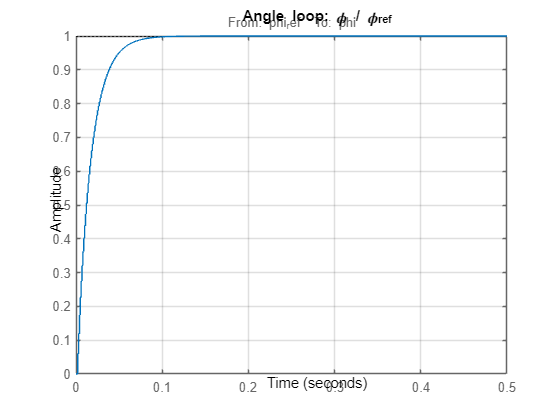

% Step response
T_phi = getIOTransfer(CL_angle_tuned,'phi_ref','phi');
figure; step(T_phi,0.5); grid on; title('Angle loop: \phi / \phi_{ref}');

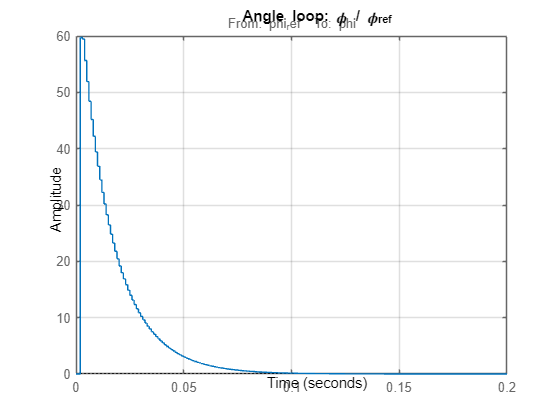

%% Angle impulse response
T_phi = getIOTransfer(CL_angle_tuned,'phi_ref','phi');
figure; impulse(T_phi,0.2); grid on; 
title('Angle loop: \phi / \phi_{ref}');

## Velocity

% --- Reuse tuned rate inner loop ---
C_rate_tuned = getBlockValue(CLwtuned,'C_rate');
C_rate_tuned.InputName  = 'e_w';
C_rate_tuned.OutputName = 'M';
G_inner.InputName = 'M'; G_inner.OutputName = 'w';
Sum_w = sumblk('e_w = w_ref - w');

CL_rate = connect(C_rate_tuned, G_inner, Sum_w, 'w_ref','w');
CL_rate.InputName  = 'w_ref';
CL_rate.OutputName = 'w';

% --- Reuse tuned angle controller (expects error!) ---
C_angle_tuned.InputName  = 'e_phi';
C_angle_tuned.OutputName = 'w_ref';
G_phi.InputName = 'w'; G_phi.OutputName = 'phi';
Sum_phi = sumblk('e_phi = phi_ref - phi');

CL_angle = connect(C_angle_tuned, CL_rate, G_phi, Sum_phi, 'phi_ref','phi');
CL_angle.InputName  = 'phi_ref';
CL_angle.OutputName = 'phi';

% --- Velocity plant ---
G_vel_c = tf(g, [1, Cv/m]);
G_vel   = c2d(G_vel_c, Ts, 'zoh');
G_vel.InputName = 'phi'; G_vel.OutputName = 'v';

% --- Velocity controller ---
C_vel = tunablePID('C_vel','PID'); C_vel.Ts = Ts;
C_vel.Kp.Minimum = 0; C_vel.Ki.Minimum = 0; 
% C_vel.Kd.Minimum = 0;
C_vel.Tf.Minimum = 1e-3; C_vel.Tf.Maximum = 1e-1;
C_vel.InputName = 'e_v'; C_vel.OutputName = 'phi_ref';

Sum_v = sumblk('e_v = v_ref - v');

% TUNING MODEL (only v exposed)
CL_vel0 = connect(C_vel, CL_angle, G_vel, Sum_v, 'v_ref','v', {'e_v'});

% Goals 
tau_vel = 1/wc_vel;      % ~0.26 s (tweak as needed)
ReqTrackVel  = TuningGoal.Tracking('v_ref','v', tau_vel);
ReqMarginVel = TuningGoal.Margins('e_v',6,45);

[CL_vel_tuned, ~] = systune(CL_vel0, [ReqTrackVel, ReqMarginVel]);

Final: Soft = 1.03, Hard = -Inf, Iterations = 53


% Extract tuned velocity PID
C_vel_tuned = getBlockValue(CL_vel_tuned,'C_vel')

C_vel_tuned =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 1.24, Ki = 0.0719, Kd = 0.0193, Tf = 0.001, Ts = 0.001
 
Name: C_vel
Sample time: 0.001 seconds
Discrete-time PIDF controller in parallel form.



% Step response
% T_vel = getIOTransfer(C_vel_tuned,'v_ref','v');
% figure; step(T_vel, 1); grid on; title('Angle loop: \v / \v_{ref}');

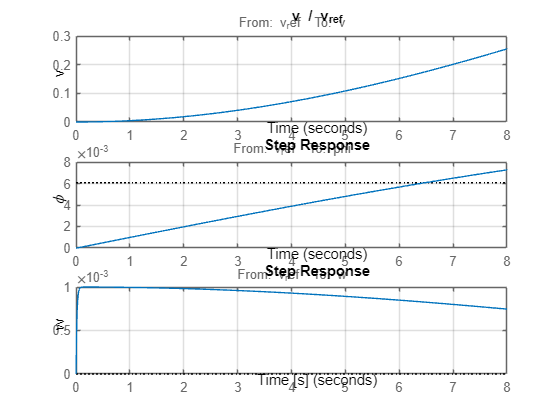

% PLOTTING MODEL (expose internal states)
% CL_vel_plot = connect(C_vel, CL_angle, G_vel, Sum_v, 'v_ref', {'v','phi','w'});
CL_vel_plot = connect(C_vel, C_angle_tuned, CL_rate, G_phi, G_vel, ...
                      Sum_v, Sum_phi, ...
                      'v_ref', {'v','phi','w'});


T_v   = getIOTransfer(CL_vel_plot,'v_ref','v');
T_phi = getIOTransfer(CL_vel_plot,'v_ref','phi');
T_w   = getIOTransfer(CL_vel_plot,'v_ref','w');

figure; 
subplot(3,1,1); step(T_v,8);   grid on; ylabel('v');   title('v / v_{ref}');
subplot(3,1,2); step(T_phi,8); grid on; ylabel('\phi');
subplot(3,1,3); step(T_w,8);   grid on; ylabel('w');   xlabel('Time [s]');

[K_rate_p,K_rate_i,K_rate_d,Tf_rate] = deal(C_rate_tuned.Kp, C_rate_tuned.Ki, C_rate_tuned.Kd, C_rate_tuned.Tf);
disp([K_rate_p,K_rate_i,K_rate_d,Tf_rate])

    3.5448    1.3598    0.0000    0.0185




[K_angle_p,K_angle_i,K_angle_d,Tf_angle] = deal(C_angle_tuned.Kp, C_angle_tuned.Ki, C_angle_tuned.Kd, C_angle_tuned.Tf);
disp([K_angle_p,K_angle_i,K_angle_d,Tf_angle])

   57.3662    0.0057    0.4483    0.0010



[K_vel_p,K_vel_i,K_vel_d,Tf_vel] = deal(C_vel_tuned.Kp, C_vel_tuned.Ki, C_vel_tuned.Kd, C_vel_tuned.Tf);
disp([K_vel_p,K_vel_i,K_vel_d,Tf_vel])

    1.2449    0.0719    0.0193    0.0010



% open("MiniHopperMTB\MLP_Pitch_Contour_6.slx");

## Position

% --- Reuse tuned rate inner loop ---
C_rate_tuned = getBlockValue(CLwtuned,'C_rate');
C_rate_tuned.InputName  = 'e_w';
C_rate_tuned.OutputName = 'M';

G_inner.InputName = 'M'; 
G_inner.OutputName = 'w';
Sum_w = sumblk('e_w = w_ref - w');

CL_rate = connect(C_rate_tuned, G_inner, Sum_w, 'w_ref','w');
CL_rate.InputName  = 'w_ref';
CL_rate.OutputName = 'w';

% --- Reuse tuned angle controller (expects error!) ---
C_angle_tuned.InputName  = 'e_phi';
C_angle_tuned.OutputName = 'w_ref';

G_phi.InputName = 'w'; G_phi.OutputName = 'phi';
Sum_phi = sumblk('e_phi = phi_ref - phi');

CL_angle = connect(C_angle_tuned, CL_rate, G_phi, Sum_phi, 'phi_ref','phi');
CL_angle.InputName  = 'phi_ref';
CL_angle.OutputName = 'phi';

% --- Reuse tuned velocity controller (expects error!) ---
C_vel_tuned.InputName  = 'e_v';
C_vel_tuned.OutputName = 'phi_ref';
G_vel.InputName = 'phi'; 
G_vel.OutputName = 'v';
Sum_vel = sumblk('e_v = v_ref - v');

% CL_vel = connect(C_vel_tuned, CL_angle, CL_rate, G_phi, Sum_phi, 'v_ref','v');
% Velocity closed loop (reusing CL_angle)

CL_vel = connect(C_vel_tuned, CL_angle, G_vel, Sum_vel, ...
                                            'v_ref','v', ...
                                            {'e_v'});

CL_vel.InputName  = 'v_ref';
CL_vel.OutputName = 'v';


% --- Position plant ---
G_pos_c = tf(1/s);
G_pos   = c2d(G_pos_c, Ts, 'zoh');
G_pos.InputName = 'v'; 
G_pos.OutputName = 'x';

% --- Position controller ---
C_pos = tunablePID('C_pos','P'); C_pos.Ts = Ts;
C_pos.Kp.Minimum = 0; 

C_pos.InputName = 'e_pos'; 
C_pos.OutputName = 'v_ref';
Sum_x = sumblk('e_pos = x_ref - x');

% === TUNING MODEL (cascade: pos→vel→angle→rate) ===
% Position closed loop (outermost)
CL_pos0 = connect(C_pos, CL_vel, G_pos, Sum_x, ...
                  'x_ref','x');

% CL_pos0 = connect(C_pos, CL_vel, G_pos, Sum_x, ...
%                   'x_ref', {'x','v','phi','w'}, ...   % outputs exposed
%                   {'e_pos','e_v','e_phi','e_w'});     % analysis points


% Goals 
tau_pos = 1 / wc_pos;      % ~0.8 s (tweak as needed)
ReqTrackPos  = TuningGoal.Tracking('x_ref','x', tau_pos);
% ReqMarginPos = TuningGoal.Margins('e_pos',6,45);

[CL_pos_tuned, ~] = systune(CL_pos0, ReqTrackPos);

Final: Soft = 1.21, Hard = -Inf, Iterations = 26


% Extract tuned velocity PI
C_pos_tuned = getBlockValue(CL_pos_tuned,'C_pos')

C_pos_tuned =
 
  Kp = 2.47
 
Name: C_pos
P-only controller.



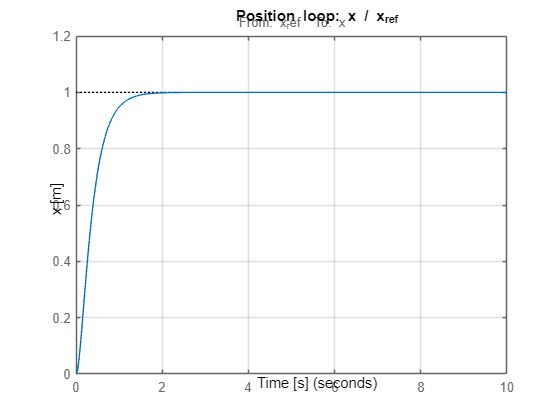

% PLOTTING MODEL (expose internal states)
% Closed-loop transfer function from x_ref to x
T_pos = getIOTransfer(CL_pos_tuned,'x_ref','x');

% Plot step response
figure;
step(T_pos, 10);    % simulate 10 seconds
grid on;
title('Position loop: x / x_{ref}');
ylabel('x [m]');
xlabel('Time [s]');

% Get transfer functions from x_ref to internal states
% T_v   = getIOTransfer(CL_pos_tuned,'x_ref','v');
% T_phi = getIOTransfer(CL_pos_tuned,'x_ref','phi');
% T_w   = getIOTransfer(CL_pos_tuned,'x_ref','w');
% 
% % Multi-plot
% figure;
% subplot(4,1,1); step(T_pos, 10); grid on; ylabel('x [m]'); title('Position response');
% subplot(4,1,2); step(T_v,   10); grid on; ylabel('v [m/s]');
% subplot(4,1,3); step(T_phi, 10); grid on; ylabel('\phi [rad]');
% subplot(4,1,4); step(T_w,   10); grid on; ylabel('w [rad/s]'); xlabel('Time [s]');

K_pos_p = deal(C_pos_tuned.Kp);
disp(K_pos_p)

    2.4744



% open("MiniHopperMTB\MLP_Pitch_Contour_7.slx");

syms w_x w_y w_z J_x J_y J_z v_x v_y v_z;
w = [w_x; w_y; w_z];
v = [v_x; v_y; v_z];
J = diag([J_x J_y J_z]);
cross(w, v)

$$ans = \left(\begin{array}{c} v_{z}\,w_{y}-v_{y}\,w_{z}\\ v_{x}\,w_{z}-v_{z}\,w_{x}\\ v_{y}\,w_{x}-v_{x}\,w_{y} \end{array}\right)$$

cross(w, J * w)

$$ans = \left(\begin{array}{c} J_{z}\,w_{y}\,w_{z}-J_{y}\,w_{y}\,w_{z}\\ J_{x}\,w_{x}\,w_{z}-J_{z}\,w_{x}\,w_{z}\\ J_{y}\,w_{x}\,w_{y}-J_{x}\,w_{x}\,w_{y} \end{array}\right)$$